- **Experiment with fspecial**

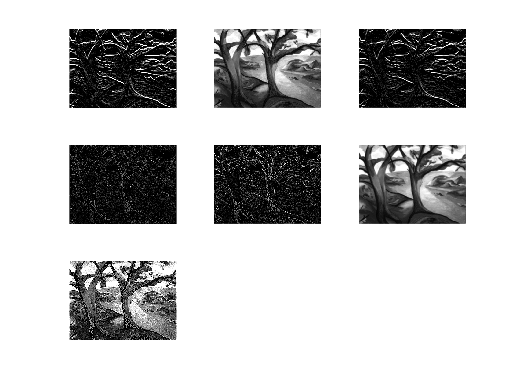

load trees
I=X;
I=ind2gray(I,map);

sobel = fspecial('sobel');
sobel_fig = filter2(sobel, I);
subplot(3,3,1)
imshow(sobel_fig);

gaussian = fspecial('gaussian');
gaussian_fig = filter2(gaussian, I);
subplot(3,3,2)
imshow(gaussian_fig)

prewitt = fspecial('prewitt');
prewitt_fig = filter2(prewitt, I);
subplot(3,3,3)
imshow(prewitt_fig)

laplacian = fspecial('laplacian');
laplacian_fig = filter2(laplacian, I);
subplot(3,3,4)
imshow(laplacian_fig)

loga = fspecial('log');
loga_fig = filter2(loga, I);
subplot(3,3,5)
imshow(loga_fig)

average = fspecial('average');
average_fig = filter2(average, I);
subplot(3,3,6)
imshow(average_fig)

unsharp = fspecial('unsharp');
unsharp_fig = filter2(unsharp, I);
subplot(3,3,7)
imshow(unsharp_fig)

  2. **Experiment**

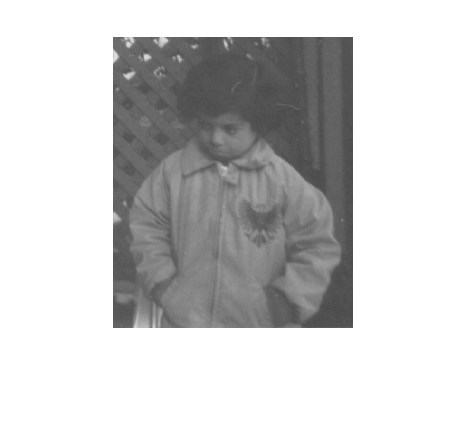

I = imread( 'pout.tif' );
% grayscale the image to type double
I=im2double(I);
% clear subplot
subplot(1, 1, 1);
%show img
imshow(I);

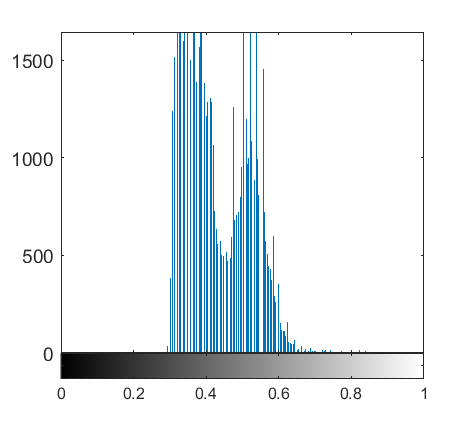

% show histogram of image
imhist(I)

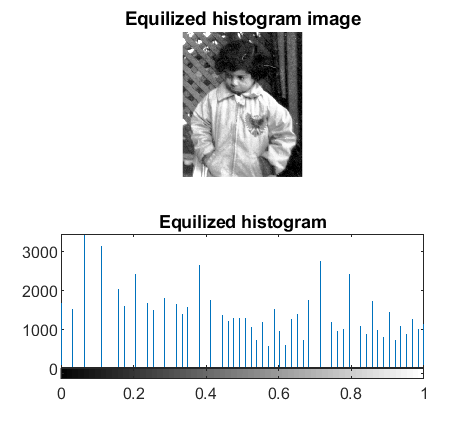

% equalize histogram
J = histeq(I);
subplot(2, 1, 1);
imshow(J)
title('Equilized histogram image')
subplot(2, 1, 2);
imhist(J,64)
title('Equilized histogram')

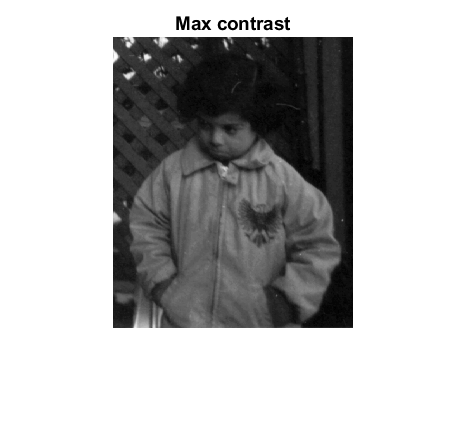

% write images to file
% imwrite(I, "pout.jpeg");
% imwrite(histeq(I), "equ_pout.jpeg");
% adjust contrast to max
subplot(1, 1, 1);
J = imadjust(I, [min(min(I)) max(max(I))], [0 1]);
imshow(J);
title('Max contrast')

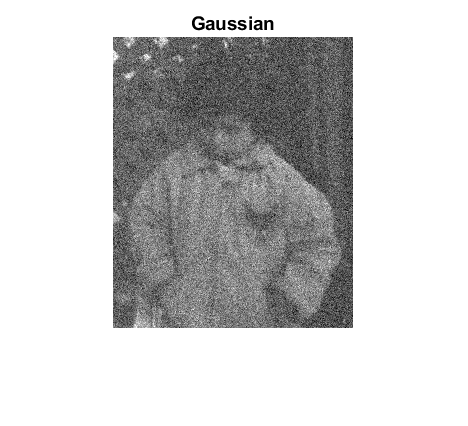

% add gaussian noise
J = imnoise(I, 'gaussian');
imshow(J)
title('Gaussian')

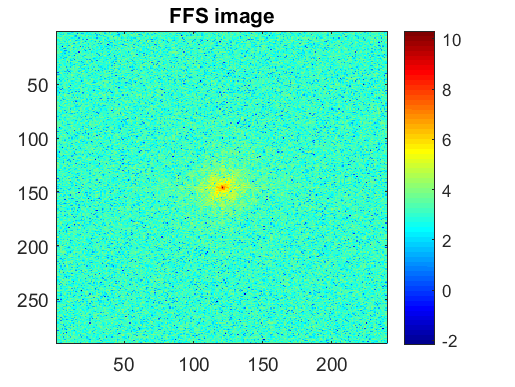


% obtain the fft of image
F=fftshift(fft2(J));
figure, colormap(jet(64)),imagesc(log(abs(F)));

colorbar,title("FFS image");

